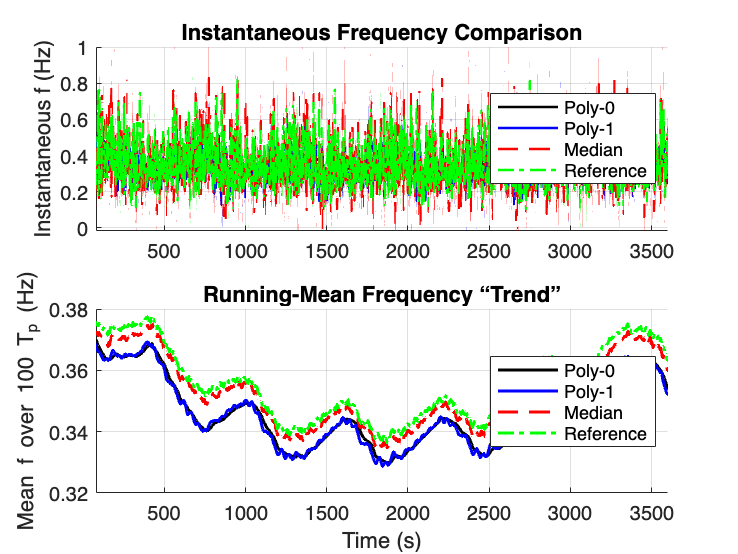

clear; clc; close all;
addpath('functions/')

%% --- Sea-state transition profile ---
T1 = 7;  H1 = 1.8;
T2 = 8;  H2 = 2.6;
dur = 1200;  % seconds per segment

% 1st segment: (H1,T1) → (H2,T2)
[eta1, t1, phi1] = fn_sea_state_transition_mod(H1, T1, H2, T2, dur);
% 2nd segment: hold at (H2,T2)
[eta2, t2, phi2] = fn_sea_state_transition_mod(H2, T2, H2, T2, dur, phi1);
% 3rd segment: (H2,T2) → (H1,T1)
[eta3, t3, phi3] = fn_sea_state_transition_mod(H2, T2, H1, T1, dur, phi2);

% stitch together
t_profile   = [ t1,           t1(end)+t2,            t1(end)+t2(end)+t3 ];
eta_profile = [ eta1,         eta2,                  eta3 ];

PSD_reverse=compute_psd_from_eta(eta2,1/dt,50);
plot(PSD_reverse.f,PSD_reverse.S)
%% --- Sea-state number (for reference plot) ---
sea_state = [ 4 + 1/t1(end)*t1, ...
              5*ones(size(t2)), ...
              5 - 1/t3(end)*t3 ];

%% --- Instantaneous-frequency estimates ---
dt = t_profile(2) - t_profile(1);
history_window = round(10*(T2)/2/dt, 1);
median_window  = round(0.055 * history_window);

f_t_median = median_inst_f(t_profile', eta_profile', history_window, median_window);
f_t_cheat  = cheat_inst_f(  t_profile', eta_profile', history_window);

f_t_o0     = poly_inst_f(t_profile', eta_profile', history_window, 0);
f_t_o1     = poly_inst_f(t_profile', eta_profile', history_window, 1);
% (you can uncomment higher orders if desired)
% f_t_o2   = poly_inst_f(t_profile', eta_profile, history_window, 2);

%% --- Trend (moving average) parameters ---
Tp = 8;                 % dominant period (s)
N  = 200;               % # of periods in smoothing window
M  = round(N * Tp / dt);% window length (samples)

% compute each trend
f0_trend = movmean(f_t_o0.inst_freq,         M);
f1_trend = movmean(f_t_o1.inst_freq,         M);
fm_trend = movmean(f_t_median.inst_freq,     M);
fc_trend = movmean(f_t_cheat.inst_freq_filtered, M);

% define your time base and x-limits
t_trim = t_profile;
xlims  = [Tp*10, t_trim(end)];

%% === PLOT: Two-panel comparison ===
figure('Name','Frequency Comparison & Trends','NumberTitle','off');

% Top: raw instantaneous frequency
subplot(2,1,1);
hold on;
  plot(t_trim, f_t_o0.inst_freq,         'k-',  'LineWidth',1.2);
  plot(t_trim, f_t_o1.inst_freq,         'b-',  'LineWidth',1.2);
  plot(t_trim, f_t_median.inst_freq,     'r--', 'LineWidth',1.2);
  plot(t_trim, f_t_cheat.inst_freq_filtered, 'g-.','LineWidth',1.2);
hold off;
grid on;
ylabel('Instantaneous f (Hz)');
title('Instantaneous Frequency Comparison');
legend({'Poly-0','Poly-1','Median','Reference'}, 'Location','best');
xlim(xlims);

% Bottom: smoothed “trend” curves
subplot(2,1,2);
hold on;
  plot(t_trim, 1./f0_trend, 'k-',  'LineWidth',1.5);
  plot(t_trim, 1./f1_trend, 'b-',  'LineWidth',1.5);
  plot(t_trim, 1./fm_trend, 'r--', 'LineWidth',1.5);
  plot(t_trim, 1./fc_trend, 'g-.','LineWidth',1.5);
hold off;
grid on;
xlabel('Time (s)');
ylabel(['Mean T over ' num2str(N) ' T_p (Hz)']);
title('Running-Mean Period “Trend”');
legend({'Poly-0','Poly-1','Median','Reference'}, 'Location','best');
xlim(xlims);